# Sitema dinamico Apple Vs Microsoft

# Codigo

Cargamos la base de datos

close all
clear all

num = xlsread("proyecto.xlsx");

Obtenemos los precios de cada serie

precio1 = num(:,2); %Precio Microsoft
precio2 = num(:,4); %Preco Apple
%precio3 = num(:,6);
corte = 700;
z = iddata([precio1 precio2]); %Convertimos los datos en iddata, que es un objeto que
%verlo como una serie de tiempo

Grafica precios

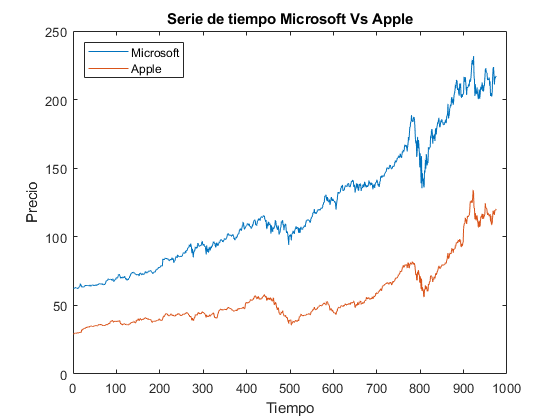

plot(precio1)
hold on
plot(precio2)
title('Serie de tiempo Microsoft Vs Apple')
xlabel('Tiempo') 
ylabel('Precio') 
legend({'Microsoft','Apple'},'Location','northwest')
hold off

Partimos en valores de estimación y de validacion para la identificacion del sistema

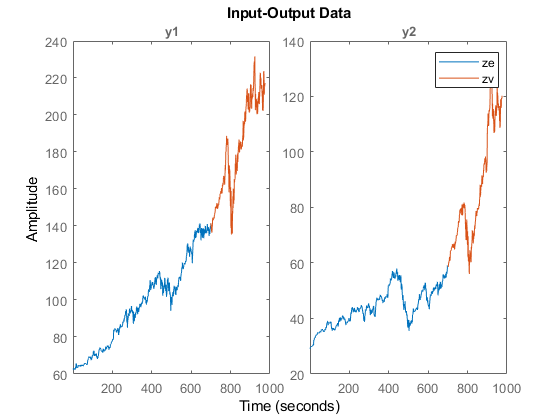

ze = z(1:corte);    % estimation data
zv = z(corte:end);  % validation data
plot(ze, zv)
legend('ze','zv')

Elegimos el modelo que solo poseen un rezago entre si.

% Seleccion Modelo
ny = 2; % number of outputs
nu = 0; % number of inputs
na = [1,1;1,1]; %Solo un rezago
%na = 2*eye(ny); % note: na must be ny-by-ny!
nb = 1*ones(ny,nu); % nb must be ny-by-nu 
nk = zeros(ny,nu); % nk must be ny-by-nu
model = arx(ze,[na nb nk])

model =
Discrete-time AR model:                                      
  Model for output "y1": A(z)y_1(t) = - A_i(z)y_i(t) + e_1(t)
    A(z) = 1 - z^-1                                          
                                                             
    A_2(z) = -0.002109 z^-1                                  
                                                             
  Model for output "y2": A(z)y_2(t) = - A_i(z)y_i(t) + e_2(t)
    A(z) = 1 - 0.9963 z^-1                                   
                                                             
    A_1(z) = -0.002027 z^-1                                  
                                                             
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=[1 1;1 1]
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using ARX on time domain data "ze".           
F

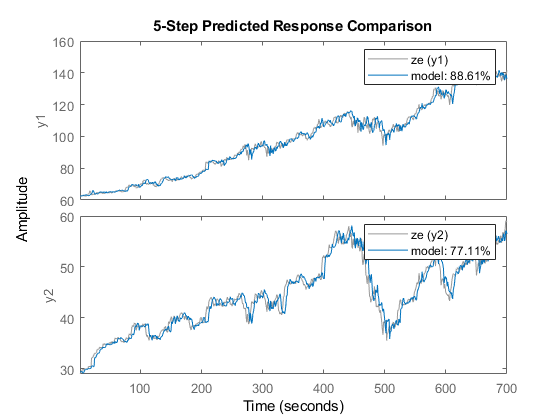

compare(ze,model,5) % Comparar modelos

% z = iddata(precio1)
% ze = z(1:corte); 
% model = arx(z,2)
% compare(ze,model,5)

## Modelamiento Error $e\left\lbrack k\right\rbrack$

Una vez modelamos la funcion del error, en la cual utilizamos una interpolación linear

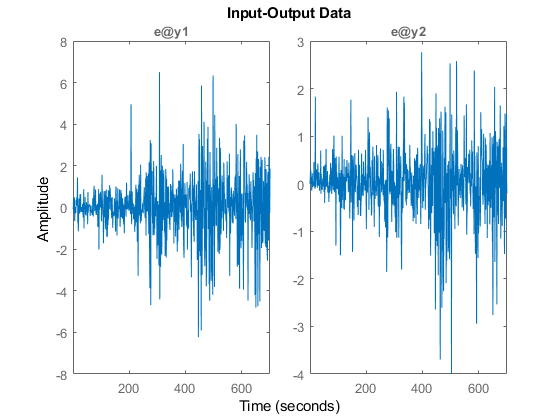

[E,R]=resid(ze,model);
plot(E)

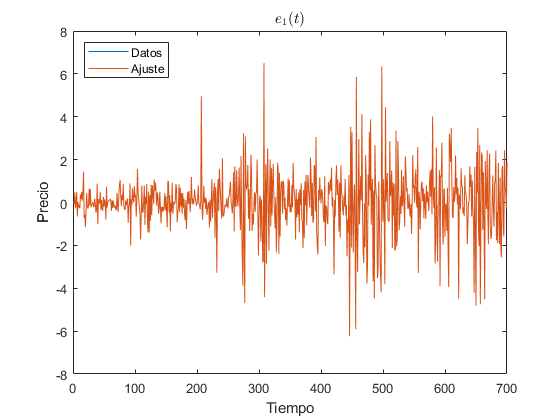

Residuales = E.OutputData;
Re1 = Residuales(:,1);
Re2 = Residuales(:,2);
t = 1:length(Residuales(:,1));
t = t';
f1 = fit(t,Re1,'linearinterp');
f2 = fit(t,Re2,'linearinterp');

plot(t, Re1)
hold on
plot(t,f1(t))
title('$$e_1(t)$$','interpreter','latex')
xlabel('Tiempo') 
ylabel('Precio') 
legend({'Datos','Ajuste'},'Location','northwest')
hold off

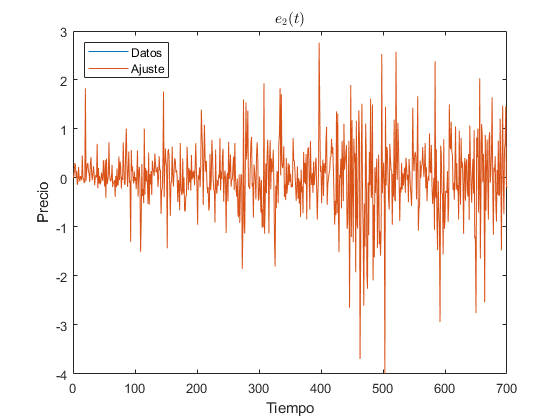

plot(t, Re2)
hold on
plot(t,f2(t))
title('$$e_2(t)$$','interpreter','latex')
xlabel('Tiempo') 
ylabel('Precio') 
legend({'Datos','Ajuste'},'Location','northwest')
hold off

## Analisis del sistema dinamico

A continuacion analizamos el sistema dinamico de manera analitica.

syms a1
syms a2

xt = [1 0.002109 ; 0.002027  0.9963]

xt =     1.0000    0.0021
    0.0020    0.9963


[V,D] = eig(xt)

V =     0.9159   -0.4149
    0.4015    0.9098


D =     1.0009         0
         0    0.9954


syms b1
syms b2
%V=subs(V,[a1 a2], resultado)
%D=subs(D,[a1 a2], resultado)
x0 = [precio1(1);precio2(1)]

x0 =    62.3000
   29.0050


x0sol = b1*V(:,1)+b2*V(:,2) == x0

$$x0sol = \left(\begin{array}{c} \frac{8249511666820053\,b_{1}}{9007199254740992}-\frac{3737465790750417\,b_{2}}{9007199254740992}=\frac{4383972691899723}{70368744177664}\\ \frac{7231928006723105\,b_{1}}{18014398509481984}+\frac{2048795192875209\,b_{2}}{2251799813685248}=\frac{8164181418017601}{281474976710656} \end{array}\right)$$

vars = [b1 b2]

$$vars = \left(\begin{array}{cc} b_{1} & b_{2} \end{array}\right)$$

e1 = solve(x0sol,vars)

e1 = struct with fields:
    b1: [1×1 sym]
    b2: [1×1 sym]


e1.b1;
e1.b2;
betas = [e1.b1 e1.b2]

$$betas = \left(\begin{array}{cc} \frac{50914525980372307238084732716224}{740829051592184820251268421979} & \frac{12011764039478571110966489456832}{7725788680889927411191799257781} \end{array}\right)$$

syms k
suma_x = 0

suma_x = 0

for i = 1:2
    suma_x = suma_x+D(i,i)^k*betas(i)*V(:,i)
end

$$suma\_x = \left(\begin{array}{c} \frac{937544589476995636959148423451997443721700089\,{\left(\frac{1126940718673809}{1125899906842624}\right)}^{k}}{14894631431677685325434699190470164942422016}\\ \frac{821897737469834025292362958832321555402029365\,{\left(\frac{1126940718673809}{1125899906842624}\right)}^{k}}{29789262863355370650869398380940329884844032} \end{array}\right)$$

$$suma\_x = \left(\begin{array}{c} \frac{937544589476995636959148423451997443721700089\,{\left(\frac{1126940718673809}{1125899906842624}\right)}^{k}}{14894631431677685325434699190470164942422016}-\frac{9609066178107277590011331138416828316782427\,{\left(\frac{8965546122848969}{9007199254740992}\right)}^{k}}{14894631431677685325434699190470164942422016}\\ \frac{821897737469834025292362958832321555402029365\,{\left(\frac{1126940718673809}{1125899906842624}\right)}^{k}}{29789262863355370650869398380940329884844032}+\frac{5267475261565710332278733479395112033982979\,{\left(\frac{8965546122848969}{9007199254740992}\right)}^{k}}{3723657857919421331358674797617541235605504} \end{array}\right)$$

suma_x = simplify(suma_x);
sol = subs(suma_x,2);
simplify(sol)

$$ans = \left(\begin{array}{c} \frac{75430960709302111107773899202599862959348716215465454265842397493931648381429}{1208396062370846056100113498337145381033735518545322206738486644999165313024}\\ \frac{8773855677768697677333272421403737676278639730742750402208354332756715597339}{302099015592711514025028374584286345258433879636330551684621661249791328256} \end{array}\right)$$

temp = zeros(2,10);
sum_f = [0;0];

for i = 1:700
    sum_f = [f1(i)+sum_f(1);f2(i)+sum_f(2)];
    temp(:,i)= subs(suma_x,i)+sum_f;
end

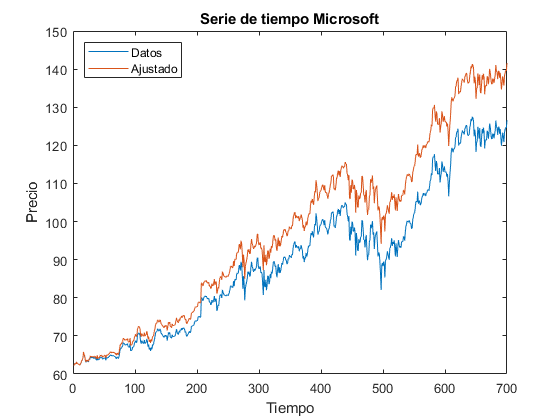

comparacion= ze.OutputData;
comparacion1 = comparacion(:,1);
plot(temp(1,:))
hold on
plot(comparacion1)
title('Serie de tiempo Microsoft')
xlabel('Tiempo') 
ylabel('Precio') 
legend({'Datos','Ajustado'},'Location','northwest')
hold off

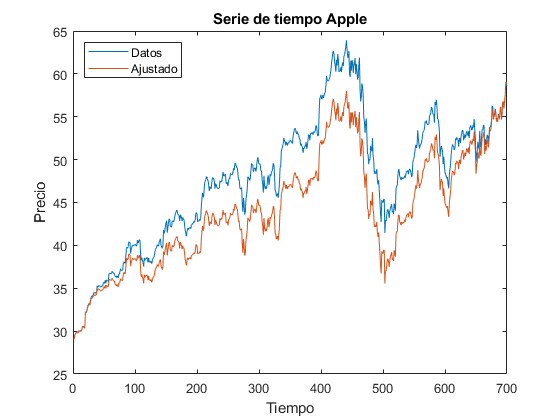


comparacion2 = comparacion(:,2);
plot(temp(2,:))
hold on
plot(comparacion2)
title('Serie de tiempo Apple')
xlabel('Tiempo') 
ylabel('Precio') 
legend({'Datos','Ajustado'},'Location','northwest')
hold off